# Atividade 07_02

Otávio Baziewicz Filho - 1942808

clc; clear; close all; 

## Detecção de bordas usando o Laplaciano (função edge)

O objetivo deste exercício é testar a afirmação “a derivada de segunda ordem não costuma ser utilizada diretamente para a detecção de bordas porque é muito sensível ao ruído”. Para isso, você pode comparar a saída o detector de bordas Laplaciano (derivada segunda) com o Sobel (derivada primeira). Como imagem de entrada use a cameraman.tif ou outra, se preferir. Lembrando: nos métodos que utilizam a derivada segunda, as bordas são obtidas detectando-se a passagem por zero.

O Laplaciano para a detecção de bordas pode ser implementado no MATLAB utilizando-se a função edge (para fazer a detecção de passagem por zero) da seguinte forma:

**h = fspecial('laplacian',0);**

**lap = edge(img,'zerocross',t,h);**

**%t é um limiar que atua na sensibilidade da %detecção das passagens por zero**

Para o Sobel, vc pode utilizar a opção edge com os parâmetros default:

**sob = edge(img,'sobel');**

Para a comparação ser justa, tente ajustar o valor **t **da detecção das passagens por zero do Laplaciano, de modo que os falsos positivos na saída sejam tão poucos quanto os observados no Sobel. Qual é a conclusão? Responda no próprio .m, na forma de comentários.

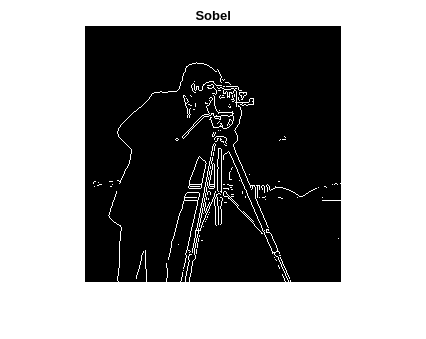

img = imread("cameraman.tif");


threshold = 0.9;

lapKernel = fspecial("laplacian", 0);
lapEdge = edge(img, "zerocross",threshold, lapKernel);

sobEdge = edge(img,"sobel");

figure, imshow(sobEdge)
title("Sobel")

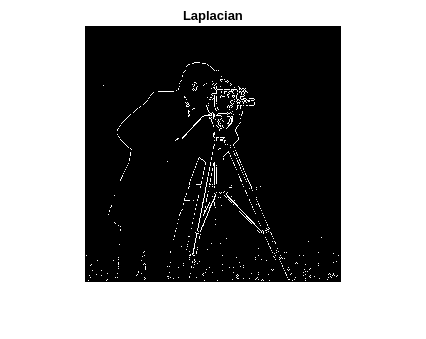



figure, imshow(lapEdge)
title("Laplacian")

## Conclusão

A aplicação do laplacinao (derivada de segunda ordem) resultou em uma detecção ruim das bordas. A medida que o ruiído era atenuado com a variação do parâmetro T, as bordas também perdiam qualidade